%Run the simulation over double support. Find the starting and ending
%points. Generate a curve that connects them in swing phase.
path(pathdef)
addpath(genpath('Experiments'))
addpath(genpath('Analysis'))
addpath(genpath('UtilityFunctions'))
addpath('Model')
addpath(genpath('Model\SimulationFunctions'))

global flowdata

flowdata = flowData;

flowdata.E_func = @MechE_func;

%Ode equation handle and tolerenaces
flowdata.eqnhandle = @dynamics;
flowdata.odeoptions = odeset('RelTol', 1e-8, 'AbsTol', 1e-10);

%Flags
flowdata.Flags.silent = false;
flowdata.Flags.ignore = true;

%Simulation parameters
flowdata.Parameters.Environment.slope = 0;   %ground slope
flowdata.Parameters.dim = 16;        %state variable dimension

%Biped Parameters
flowdata.Parameters.Biped = load('MassInertiaGeometry');

%Discrete Mappings 
flowdata.setPhases({'Heel','Flat','Toe'})
flowdata.setConfigs({})
e1 = struct('name','HeelStrike','nextphase','Heel','nextconfig','');
e2 = struct('name','FootSlap','nextphase','Flat','nextconfig','');
e3 = struct('name','Toe','nextphase','Toe','nextconfig','');
flowdata.Phases.Toe.events = {e1};
flowdata.Phases.Heel.events = {e2};
flowdata.Phases.Flat.events = {e3};

flowdata.End_Step.event_name = 'HeelStrike';
flowdata.End_Step.map = @map_End_Step;

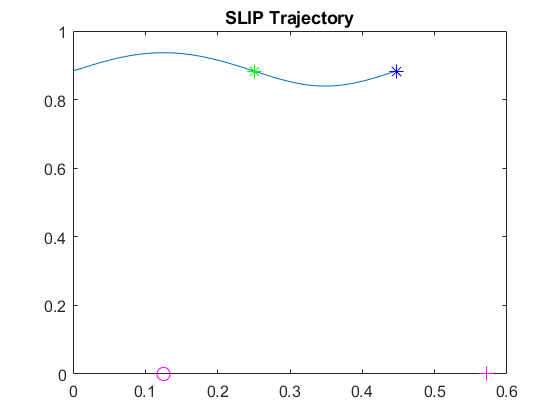

%Trajectory
load('slip_walk.mat') 
pf1 = out_extra.steps{1}.phases{2}.foot_pos_1;
pf2 = out_extra.steps{1}.phases{2}.foot_pos_2;
indexi = find(tout==out_extra.steps{1}.phases{2}.tstart,1);
indexf = find(tout==out_extra.steps{1}.phases{2}.tend,1);
zs_dsupp = xout(indexi,:);
zf_dsupp = xout(indexf,:);
close all
plot(xout(:,1),xout(:,2))
hold on
plot(zs_dsupp(1),zs_dsupp(2),'g*','MarkerSize',10)
plot(zf_dsupp(1),zf_dsupp(2),'b*','MarkerSize',10)
plot(pf1(1),pf1(2),'m+','MarkerSize',10)
plot(pf2(1),pf2(2),'mo','MarkerSize',10)
title('SLIP Trajectory')

%fmincon Optimization to solve inverse kinematic problem at the end of SLIP
%Double Support (mapping SLIP cords into Flat Foot Biped cords)

%negate all xvalues because flat model goes backwards
pf1(1) = -pf1(1);
pf2(1) = -pf2(1);
zs_dsupp(1) = -zs_dsupp(1);
zs_dsupp(3) = -zs_dsupp(3);
zf_dsupp(1) = -zf_dsupp(1);
zf_dsupp(3) = -zf_dsupp(3);

dim = flowdata.Parameters.dim;
A=[];
b=[];

%Constrain stance heel to ground
Aeq = zeros(4,16);
Aeq(1,1) = 1;
Aeq(2,2) = 1;
Aeq(3,9) = 1;
Aeq(4,10) = 1;
beq = [pf1(1);pf1(2);0;0];
load('xi.mat')
x0 = xi;
x0(1)=pf1(1);
x0(2)=pf1(2);

%Bounded the joints to be +- 90 degree rotation from initial condition
lb = x0 - [pi/2*ones(1,8),inf(1,8)];
ub = x0 + [pi/2*ones(1,8),inf(1,8)];
lb(1:2)=-inf;
lb(7) = xi(7)-1e-3;
ub(1:2)= inf;

options = optimoptions('fmincon','MaxFunctionEvaluations',10000,'OptimalityTolerance',1e-6,'Display','iter-detailed');
fun = @(x)IK_SLIP_pos_cost(x,zs_dsupp,pf2);
xs_dsupp1 = fmincon(fun,x0,A,b,Aeq,beq,lb,ub,[],options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    4.050267e-01    0.000e+00    5.686e-01
    1      35    2.547262e-01    0.000e+00    1.590e+00    4.177e-01
    2      53    2.698489e-01    1.345e-16    1.717e+00    2.138e-01
    3      70    2.090435e-01    4.509e-17    4.592e-01    2.585e-01
    4      87    2.050663e-01    3.488e-17    7.144e-01    7.717e-01
    5     104    1.965960e-01    7.602e-18    9.982e-02    5.130e-02
    6     121    1.943900e-01    8.809e-18    3.044e-02    4.261e-02
    7     138    1.929936e-01    1.938e-19    4.080e-02    6.015e-02
    8     155    1.920184e-01    2.944e-18    3.396e-02    6.581e-02
    9     172    1.918045e-01    3.899e-20    2.000e-02    2.200e-02
   10     189    1.915435e-01    9.248e-19    4.670e-03    3.860e-02
   11     206    1.905631e-01    1.332e-18    2.513e-02    1.849e-01
   12     223    1.901831e-01    3.343e-19    1

play_handels_messiah

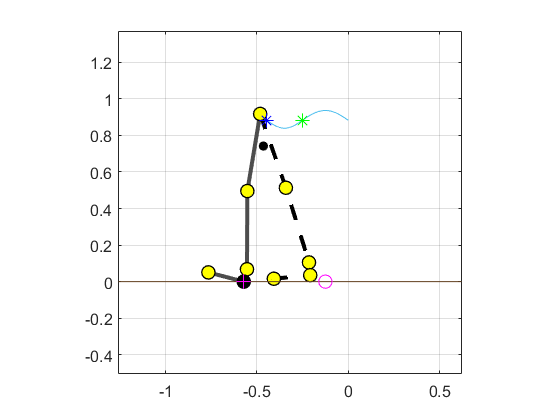

draw7Link(x0','na');
hold on
plot(-xout(:,1),xout(:,2))
plot(zs_dsupp(1),zs_dsupp(2),'g*','MarkerSize',10)
plot(zf_dsupp(1),zf_dsupp(2),'b*','MarkerSize',10)
plot(pf1(1),pf1(2),'m+','MarkerSize',10)
plot(pf2(1),pf2(2),'mo','MarkerSize',10)
hold off

draw7Link(xs_dsupp1','na');

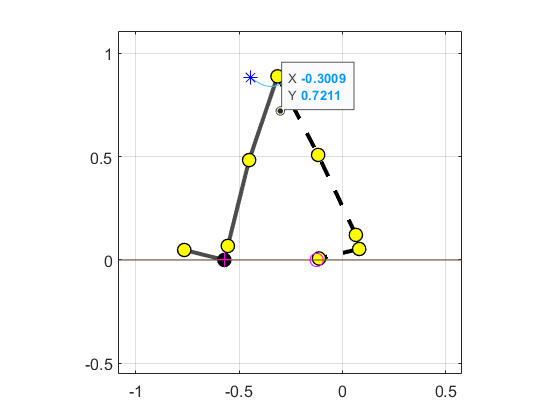

hold on
plot(-xout(:,1),xout(:,2))
plot(zs_dsupp(1),zs_dsupp(2),'g*','MarkerSize',10)
plot(zf_dsupp(1),zf_dsupp(2),'b*','MarkerSize',10)
plot(pf1(1),pf1(2),'m+','MarkerSize',10)
plot(pf2(1),pf2(2),'mo','MarkerSize',10)
old off

%find velocities
dim = flowdata.Parameters.dim;
A=[];
b=[];

%Use pos optimzation result as constraint and initial guess
Aeq = [eye(8,8),zeros(8,8);zeros(2,16)];
Aeq(9,9)=1;
Aeq(10,10) = 1;
beq = xs_dsupp1(1:10);

lb = [];
ub = [];

fun = @(x)IK_SLIP_vel_cost(x,zs_dsupp);
xs_dsupp2 = fmincon(fun,xs_dsupp1,A,b,Aeq,beq,lb,ub,[],options);

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0      17    1.241575e+00    0.000e+00    1.824e-01
    1      34    1.205311e+00    0.000e+00    4.589e-01    3.267e-01
    2      51    1.189567e+00    2.335e-17    7.345e-02    1.177e-01
    3      68    1.163663e+00    1.926e-18    1.227e-01    3.175e-01
    4      85    1.109847e+00    1.388e-17    3.283e-01    9.257e-01
    5     102    1.055405e+00    3.036e-18    3.528e-01    1.250e+00
    6     119    1.028341e+00    2.082e-17    1.725e-01    7.406e-01
    7     136    1.024345e+00    2.776e-17    3.808e-02    6.675e-02
    8     153    1.023686e+00    3.469e-18    1.392e-02    5.684e-02
    9     170    1.021810e+00    6.505e-19    4.939e-02    1.416e-01
   10     187    1.017221e+00    3.626e-20    9.804e-02    3.494e-01
   11     204    1.005044e+00    1.388e-17    1.852e-01    9.860e-01
   12     221    9.744065e-01    1.388e-17    3

play_handels_messiah
xi_slip_dsupp = xs_dsupp2;
save('xi_slip_dsupp.mat','xi_slip_dsupp');

% n = flowdata.Parameters.dim/2;
% R = [ zeros(1,n);
%       zeros(1,n);
%       0,0,ones(1,n-2);[zeros(n-3,3),flip(-1*eye(n-3),1)]];
% R_sup = [R,zeros(n);zeros(n),R];
% 
% xe = xout(end,:);
% xs = (R_sup*xi')';
% params = cell2mat(flowdata.Parameters.Biped.values);
% 
% M = M_func(xs',params);
% A = A_Swap_func(xs',params);
% C = A_SSupp_func(xs',params);
% a = rank(A);
% c = rank(C);
% 
% B = [M;A];
% I = [M,A';C,zeros(c,a)];
% 
% qdot_next = xs(n+1:end)';
% temp = I\B*qdot_next;
% q_e = xs(1:n)';
% qdot_e = temp(1:n);
% 
% nC = null(C);
% P = nC*(nC'*nC)^-1*nC';
% 
% xtest = [q_e;P*qdot_e]';
% xtest(1:2) = xtest(1:2); 
% 
% h1 = Foot_Sw_pos_func(xf',params);
% h1dot = Foot_Sw_vel_func(xf',params);
% 
% h2 = Foot_Sw_pos_func(xtest',params);
% h2dot = Foot_Sw_vel_func(xtest',params);
% 
% p1 = [h1(1:2,4)';h1dot(1:2,4)'];
% p2 = [h2(1:2,4)';h2dot(1:2,4)'];
% 
% Bspline = BezierSpline(3);
% Bspline.MatchEndPoints(p1,p2,1)
% [x,y] = Bspline(linspace(0,1,100));
% draw4Link(xi','na');
% plot(p1(1),p1(2),'b*');
% plot(p2(1),p2(2),'r*');
% plot(x,y, 'blue');